clear
close all
clc

mot.k = 5.2;
mot.T = 0.03;
s = tf('s');
P = mot.k / (s * (mot.T * s + 1));
[numP, denP] = tfdata(P, 'v');

pid.Kp = 8.7;
pid.Ki = 120;
pid.Kd = 0.16;
pid.Tl = 0.0053;
Ts = 0.01; % [s]
z = tf('z', Ts);
sb = (1 - z^-1) / Ts;
pidD = pid.Kd * sb / (pid.Tl * sb + 1);
[numD, denD] = tfdata(pidD, 'v');

umax = 10; % [V]
res = 250; % [ppr]
d0 = 3.5; % [V]
deg2pulse = res / 360;
pulse2deg = 360 / res;
deg2rad = pi / 180;
rad2deg = 180 / pi;
rad2pulse = rad2deg * deg2pulse;
pulse2rad = pulse2deg * deg2rad;

r.A = 50; % [deg]
r.w = 2 * pi; % [rad/s]

La posizione è descritta da A sin (wt), dunque la velocità è A w cos (wt).

open_system("ex3_sim1m.slx")
set_param("ex3_sim1m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "5")
sim("ex3_sim1m")

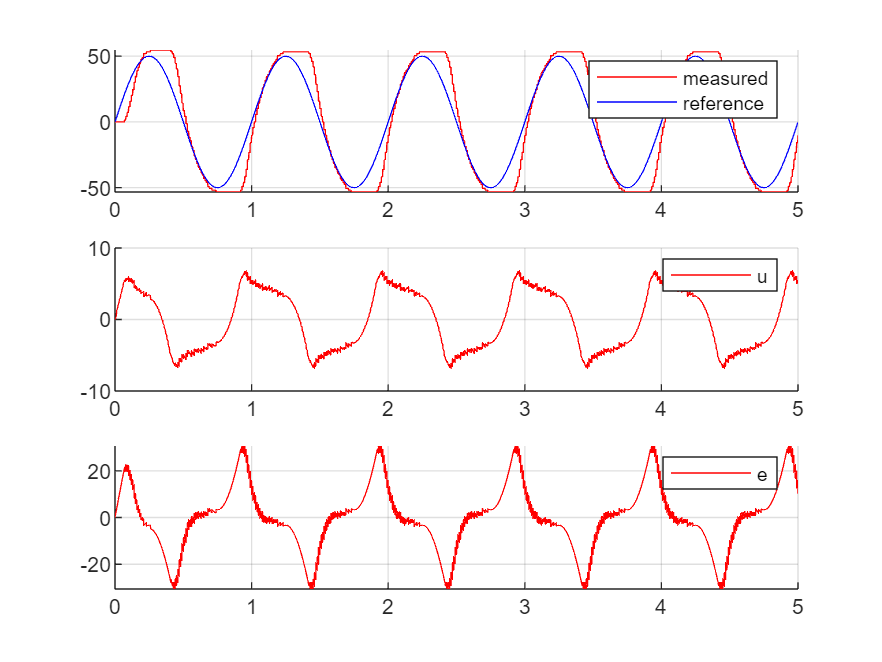

close all
figure(1)
subplot(3, 1, 1)
hold on
grid on
plot(sim_res1.time, sim_res1.signals(1).values, "r")
plot(sim_res1.time, sim_res1.signals(2).values, "b")
legend("measured", "reference")

subplot(3, 1, 2)
hold on
grid on
plot(sim_res1.time, sim_res1.signals(4).values, "r")
legend("u")

subplot(3, 1, 3)
hold on
grid on
plot(sim_res1.time, sim_res1.signals(3).values, "r")
legend("e")

open_system("ex3_sim2m.slx")
set_param("ex3_sim2m", "SolverType", "Variable-Step", "Solver", "ode45", ...
    "MaxStep", "0.0001", "StopTime", "5")
sim("ex3_sim2m")

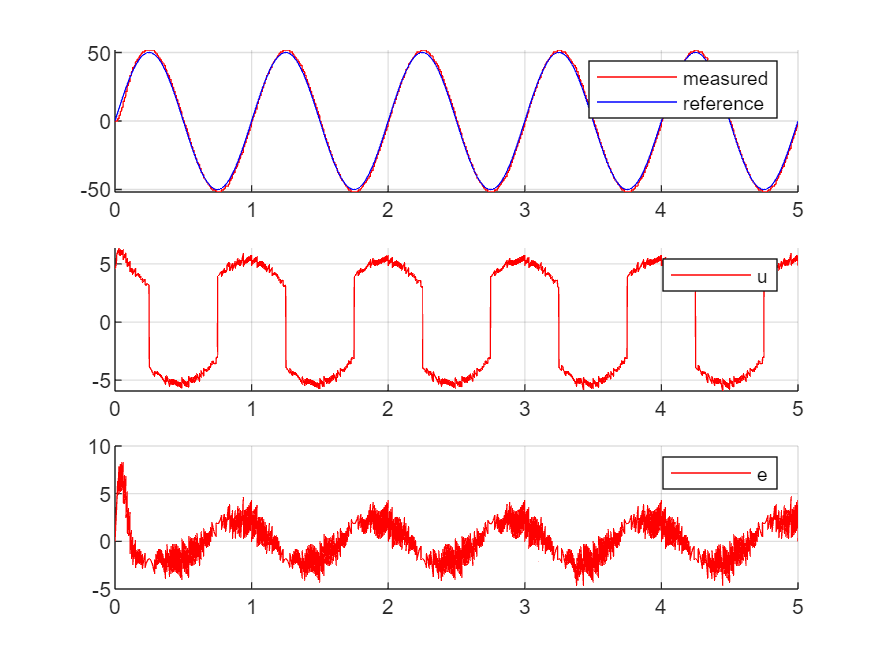

close all
figure(2)
subplot(3, 1, 1)
hold on
grid on
plot(sim_res2.time, sim_res2.signals(1).values, "r")
plot(sim_res2.time, sim_res2.signals(2).values, "b")
legend("measured", "reference")

subplot(3, 1, 2)
hold on
grid on
plot(sim_res2.time, sim_res2.signals(4).values, "r")
legend("u")

subplot(3, 1, 3)
hold on
grid on
plot(sim_res2.time, sim_res2.signals(3).values, "r")
legend("e")